# Electric Field Of A Charge in Uniform Relativistic Motion

Live Script exploring the electric field lines of a uniformly moving charge.

Author: D. Carlsmith

## Introduction

This educational Live Script visualizes the electric field of a point charge in uniform motion. As the charge velocity approaches the speed of light, the field lines undergo dramatic relativistic compression toward the plane perpendicular to the velocity. The visualization represents electric flux by using rejection sampling to distribute field lines with angular density proportional to the relativistic field strength. 

This script may interest students and instructors of physics with a background in intermediate electromagnetism and special relativity. 'Try this' suggestions,  hyperlinks, and references are included for further exploration.

Additional educational Live Scripts by the author are available [here](https://www.mathworks.com/matlabcentral/fileexchange/?q=carlsmith&sort=date_desc_submitted).

## Background Information

**Lienard-Wiechert Fields**

The electromagnetic fields of a point charge in arbitrary motion are given by the [Lienard-Wiechert formulas](https://en.wikipedia.org/wiki/Li%C3%A9nard%E2%80%93Wiechert_potential). For the special case of uniform (constant velocity) motion, the electric field takes a remarkably simple form first derived by Oliver Heaviside in 1888:


$$\vec{E} = \frac{q}{4\pi\epsilon_0} \frac{(1-\beta^2)}{(1-\beta^2\sin^2\theta)^{3/2}} \frac{\hat{r}}{r^2}$$


where $\beta = v/c$ is the velocity as a fraction of the speed of light, $\theta$ is the angle from the velocity direction, and $\hat{r}$ points from the charge's instantaneous position to the field point. 

**Key Features**

Several important features distinguish this relativistic field from the static Coulomb field:

- The field remains **radial** (points directly away from the charge)

- The field magnitude depends on the angle $\theta$ from velocity

- Perpendicular to v ($\theta = 90\degree $): $E_\perp = \gamma E_0$

- Parallel to v ($\theta = 0\degree , 180\degree $): $E_\parallel = E_0/\gamma^2$

- The ratio $E_\perp/E_\parallel = \gamma^3$ can be enormous at high speeds

where $\gamma = 1/\sqrt{1-\beta^2}$ is the Lorentz factor and $E_0 = q/(4\pi\epsilon_0 r^2)$ is the Coulomb field.

**Field Line Density and Flux**

Electric field lines are conventionally drawn such that their density (number per unit area perpendicular to the lines) represents the field magnitude. For a static charge, this requires uniform angular distribution of lines (isotropic field). For a moving charge, field lines must be weighted by the anisotropic field strength.

This script uses **rejection sampling** to achieve the correct distribution: directions are generated uniformly on the sphere, then accepted with probability proportional to $|E(\theta)|$. The result is more lines perpendicular to v (where E is strong) and fewer lines parallel to v (where E is weak).

**The Magnetic Field**

A uniformly moving charge also produces a magnetic field:


$$\vec{B} = \frac{1}{c}\vec{v} \times \vec{E} = \frac{\vec{v}}{c^2} \times \vec{E}$$


In units where c = 1, $|\vec{B}|/|\vec{E}| = \beta$. The magnetic field circulates around the velocity direction and is always perpendicular to both v and E. When $v\simeq c$, the electric and magnetic fields sensed by a fixed charge are similar to a pulse of electromagnetic radiation traveling with the moving particle. This is the basis for the Weizsäcker-Williams approximation or method of virtual quanta used to calculate [bremsstrahlung](https://en.wikipedia.org/wiki/Bremsstrahlung) and related electromagnetic processes.

These formulae for the electric and magnetic fields of a charge in uniform motion are perhaps most elegantly derived not from the Lienard-Wiechert formulas expressed in terms of retarded time but instead by [Lorentz transformation](https://en.wikipedia.org/wiki/Lorentz_transformation) of the static Coulomb field in the rest frame of the charge to the frame in which it is moving, using the fact that the fields transform jointly as a 4-tensor. In any case, it is implicit that the charge has been in uniform motion for an infinite time.

## Initialize

close all;
clear;
clc;
tic;

## Set Parameters

### Try this: Set the particle speed in units of light speed.

Adjust beta to see how the field line distribution changes: * beta = 0: Static charge (uniform field lines) * beta = 0.5: Mild compression (gamma = 1.15) * beta = 0.8: Noticeable pancaking (gamma = 1.67) * beta = 0.95: Dramatic compression (gamma = 3.2) * beta = 0.99: Extreme pancaking (gamma = 7.1)

beta_default = 0.8;
beta = 0.954;

### Try this: Set the number of field lines to display.

n_lines_default = 100;
n_lines = 240;

## Calculate Relativistic Parameters

Compute the Lorentz factor and field strength ratio

if beta >= 1
    error('beta must be less than 1');
end

gamma = 1 / sqrt(1 - beta^2);

fprintf('Relativistic Parameters\n');

Relativistic Parameters


fprintf('=======================\n');

fprintf('beta  = v/c = %.4f\n', beta);

beta  = v/c = 0.9540


fprintf('gamma = 1/sqrt(1-beta^2) = %.4f\n', gamma);

gamma = 1/sqrt(1-beta^2) = 3.3355


fprintf('E_perp / E_parallel = gamma^3 = %.2f\n', gamma^3);

E_perp / E_parallel = gamma^3 = 37.11


fprintf('\n');

## Generate Field Lines with Flux-Weighted Distribution

Use rejection sampling to distribute field lines according to `E(theta)`

fprintf('Generating %d field lines...\n', n_lines);

Generating 240 field lines...


% Generate weighted directions using rejection sampling

[dir_x, dir_y, dir_z] = generate_weighted_directions_local(beta, n_lines);
fprintf('Field lines generated.\n\n');

Field lines generated.



## Plot 1: 3D Perspective View

Side view showing the relativistic compression ("pancaking") of field lines

figure('Position', [100, 100, 800, 600], 'Color', 'w');
hold on;

Field line parameters

r_start = 0.05;
r_end = 3.5;

Plot each field line

for i = 1:n_lines
    dir_vec = [dir_x(i); dir_y(i); dir_z(i)];
    

            Line from r_start to r_end along this direction

    t = linspace(r_start, r_end, 100);
    x_line = t * dir_vec(1);
    y_line = t * dir_vec(2);
    z_line = t * dir_vec(3);
    

          Color based on angle from velocity: red = transverse, blue = parallel

    cos_theta = abs(dir_vec(2));
    base_color = [1-cos_theta, 0.1, cos_theta];
    
    plot3(x_line, y_line, z_line, '-', 'Color', base_color, 'LineWidth', 1.0);
end

Draw charge at origin

scatter3(0, 0, 0, 300, 'r', 'filled');
text(0.2, 0.2, 0.4, '+q', 'FontSize', 16, 'FontWeight', 'bold');

Velocity arrow (attached to charge at origin)

quiver3(0, 0, 0, 0, 2.5, 0, 0, 'k', 'LineWidth', 4, 'MaxHeadSize', 0.4);
text(0.2, 2.8, 0, 'v', 'FontSize', 18, 'FontWeight', 'bold');

Draw transverse plane outline (y=0)

theta_circle = linspace(0, 2*pi, 100);
plot3(3.5*cos(theta_circle), zeros(size(theta_circle)), 3.5*sin(theta_circle), ...
    'k-', 'LineWidth', 2);

Formatting

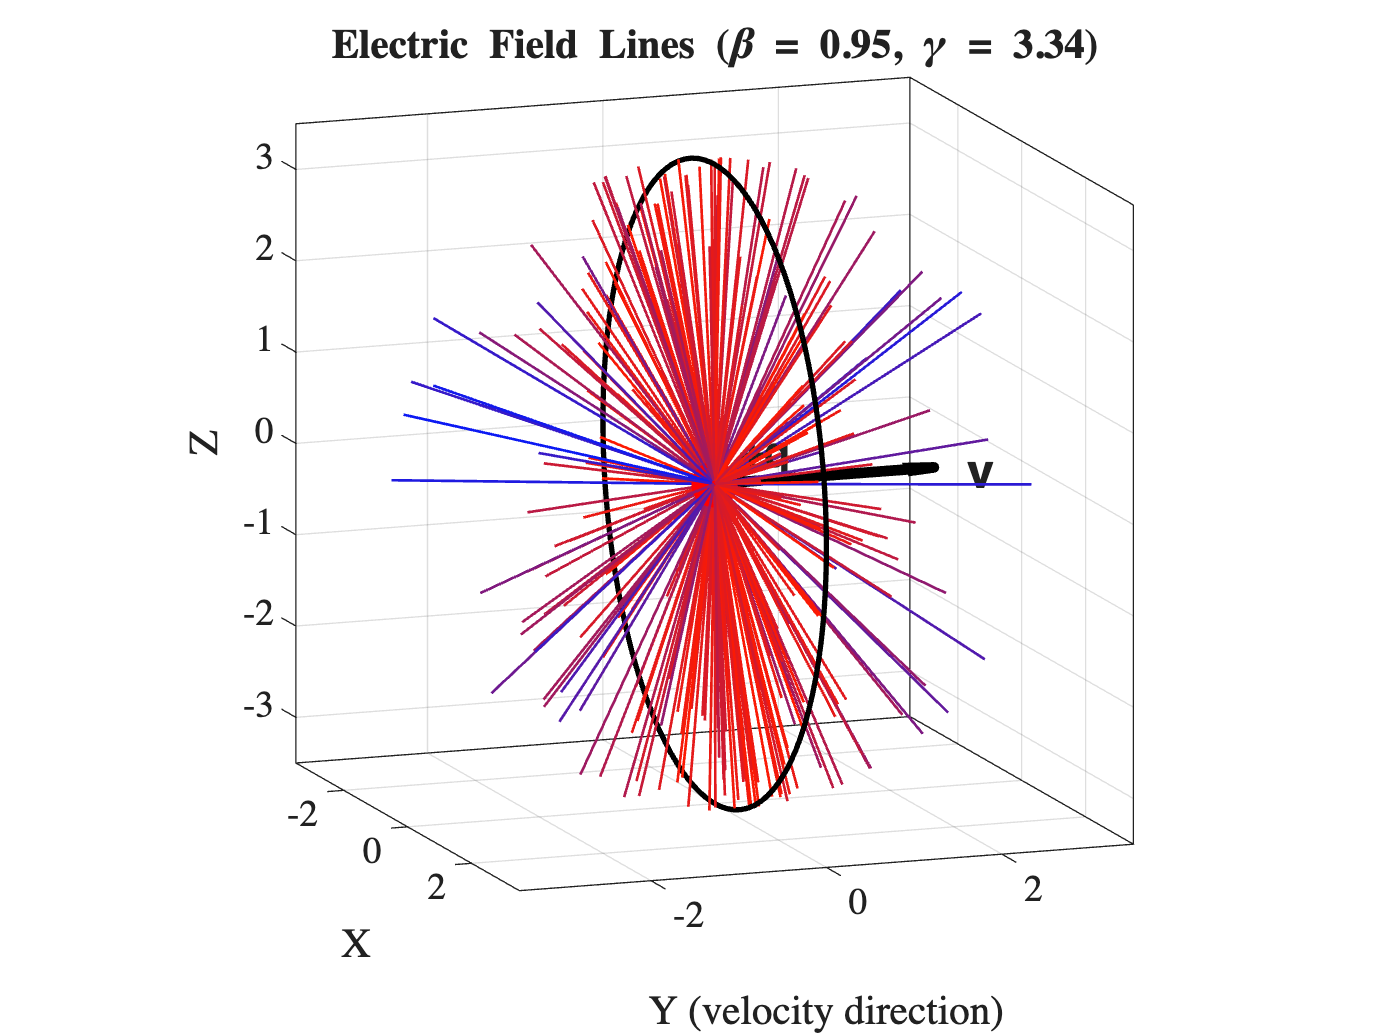

xlabel('X', 'FontSize', 14);
ylabel('Y (velocity direction)', 'FontSize', 14);
zlabel('Z', 'FontSize', 14);
title(sprintf('Electric Field Lines (\\beta = %.2f, \\gamma = %.2f)', beta, gamma), ...
    'FontSize', 16);

axis equal;
xlim([-3.5, 3.5]);
ylim([-3.5, 3.5]);
zlim([-3.5, 3.5]);
view(70, 12);  % Side view to show pancaking
grid on;
box on;
hold off;

## Plot 2: View Along Velocity Direction

Looking along v shows the radial pattern and enhanced transverse flux

figure('Position', [150, 150, 600, 600], 'Color', 'w');
hold on;

Plot field lines

for i = 1:n_lines
    dir_vec = [dir_x(i); dir_y(i); dir_z(i)];
    
    t = linspace(r_start, r_end, 100);
    x_line = t * dir_vec(1);
    y_line = t * dir_vec(2);
    z_line = t * dir_vec(3);
    
    cos_theta = abs(dir_vec(2));
    base_color = [1-cos_theta, 0.1, cos_theta];
    
    plot3(x_line, y_line, z_line, '-', 'Color', base_color, 'LineWidth', 1.0);
end

Charge

scatter3(0, 0, 0, 300, 'r', 'filled');

Velocity into page marker

theta_small = linspace(0, 2*pi, 50);
plot(0.25*cos(theta_small), 0.25*sin(theta_small), 'k-', 'LineWidth', 2);
plot(0, 0, 'kx', 'MarkerSize', 15, 'LineWidth', 3);
text(0.5, -0.5, 'v (into page)', 'FontSize', 12);

Reference circles

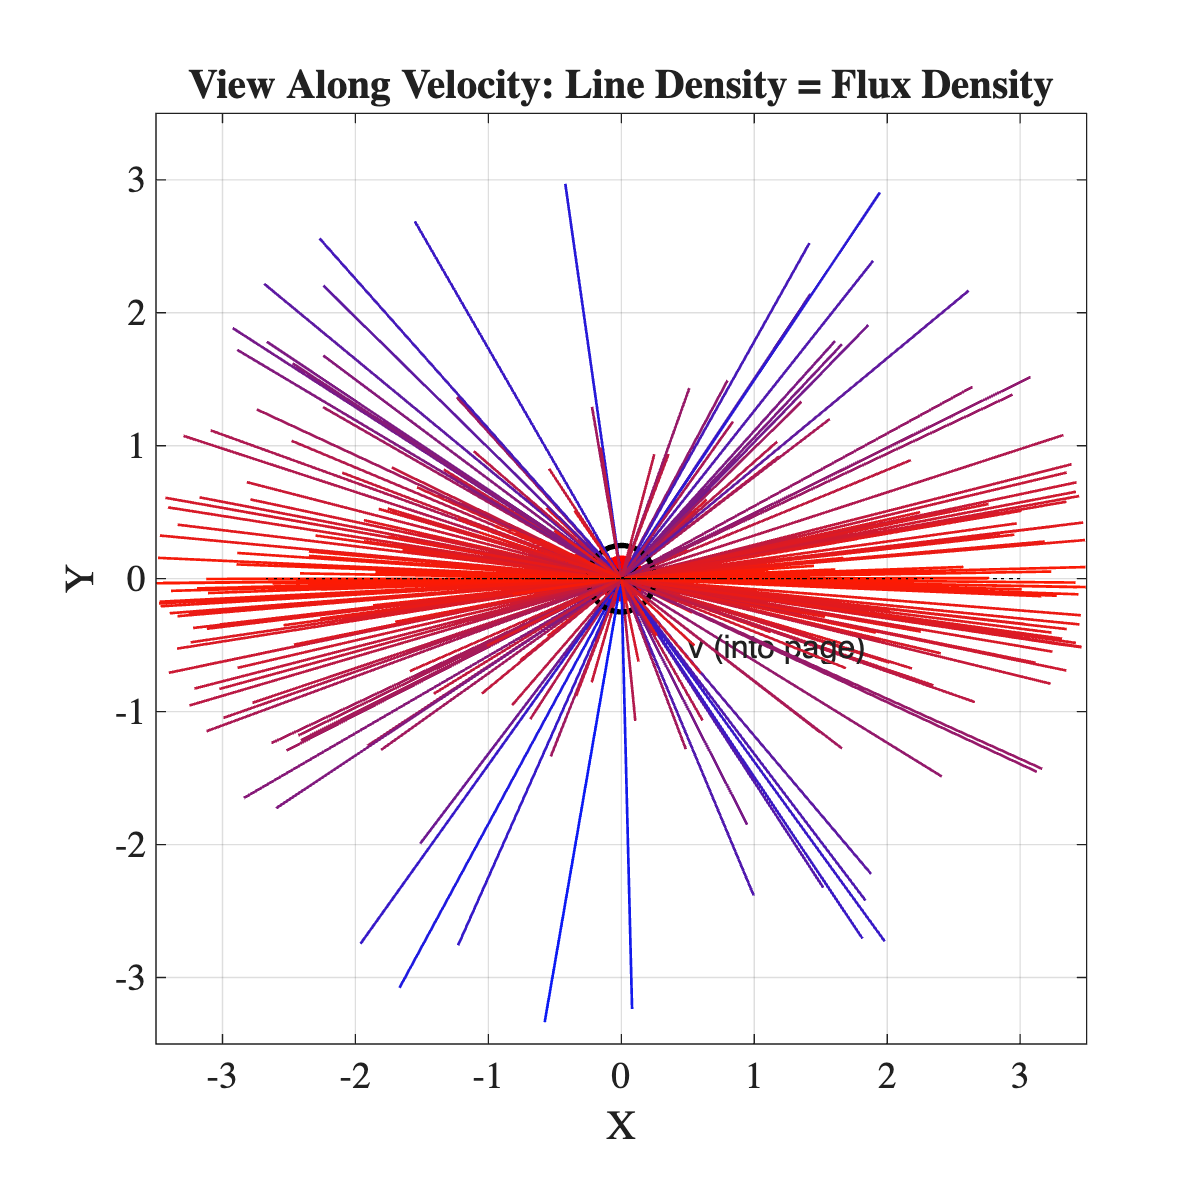

for r = [1, 2, 3]
    plot3(r*cos(theta_circle), zeros(size(theta_circle)), r*sin(theta_circle), ...
        'k:', 'LineWidth', 0.5);
end


xlabel('X', 'FontSize', 14);
ylabel('Y', 'FontSize', 14);
zlabel('Z', 'FontSize', 14);
title('View Along Velocity: Line Density = Flux Density', 'FontSize', 14);
axis equal;
xlim([-3.5, 3.5]);
ylim([-3.5, 3.5]);
zlim([-3.5, 3.5]);
view(0, 90);  % View from +y direction
grid on;
box on;
hold off;

## Plot 3: Comparison at Different Velocities

Compare field line distributions for non-relativistic, moderate, and high speeds

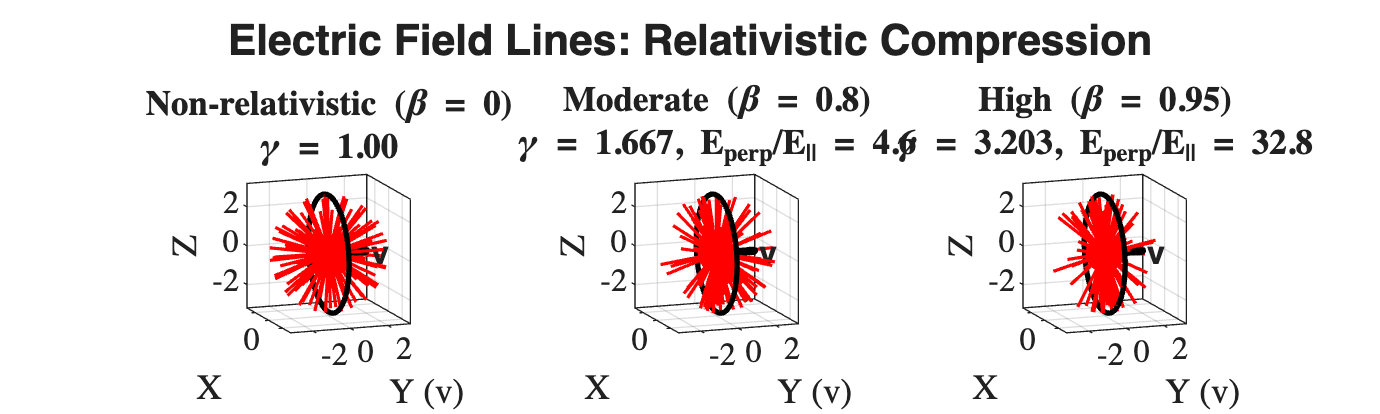

figure('Position', [200, 100, 1500, 450], 'Color', 'w');

### Try this: Set velocities for electric field comparisons.

Adjust the values below. Note each must be less than 1 and zero or greater.

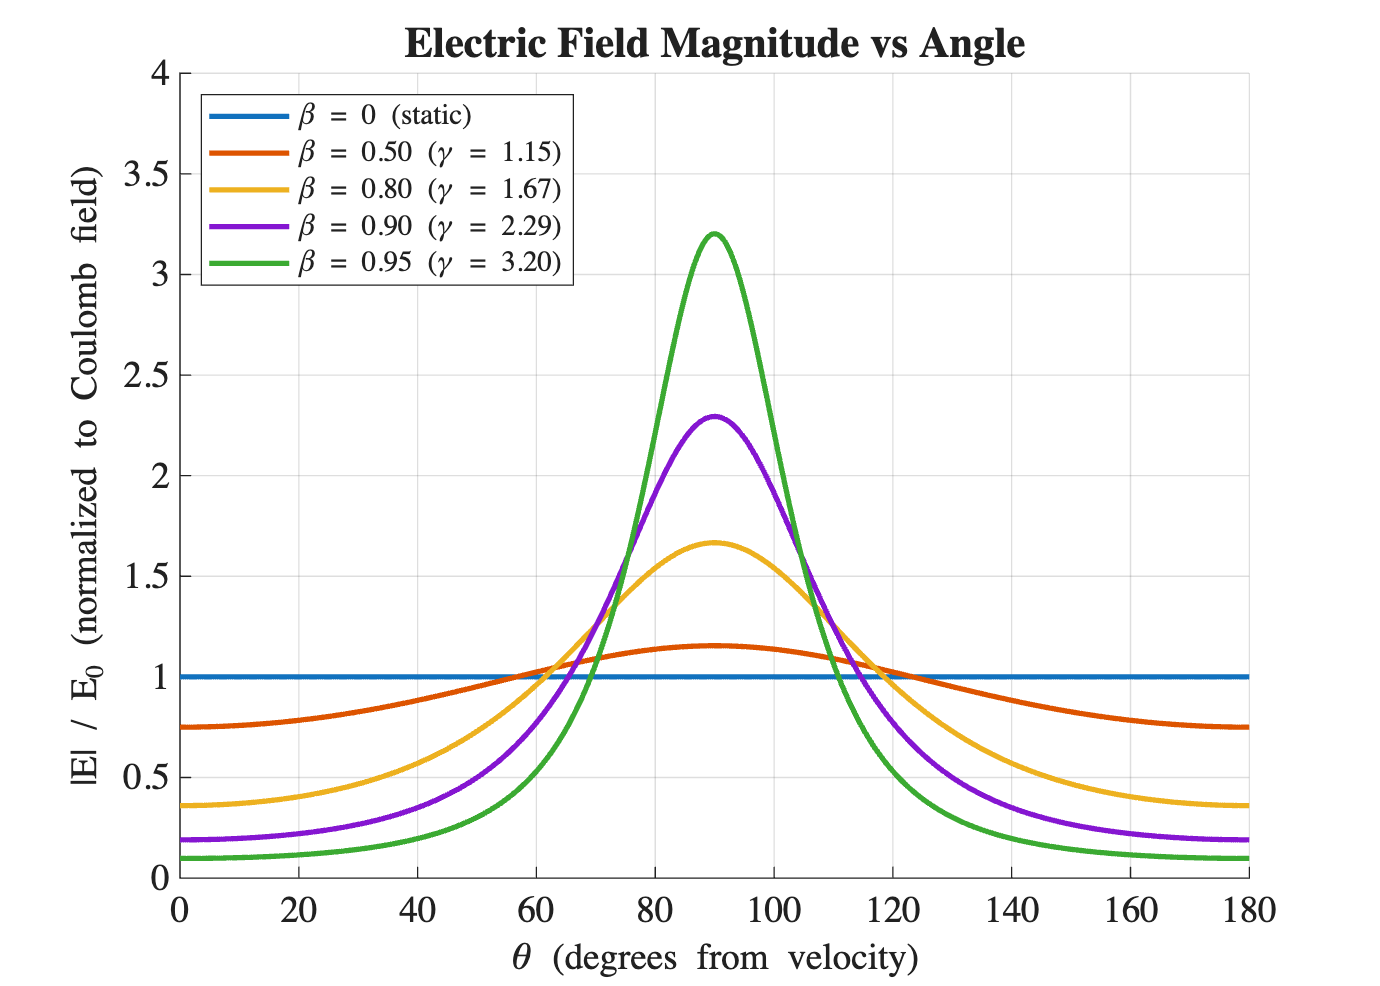

beta_values = [0.0, 0.8, 0.95];
n_compare = 100;
titles_str = {'Non-relativistic (\beta = 0)', ...
              'Moderate (\beta = 0.8)', ...
              'High (\beta = 0.95)'};

for idx = 1:3
    beta_i = beta_values(idx);
    
    if beta_i < 0.01
        gamma_i = 1;
        [x0, y0, z0] = fibonacci_sphere_local(n_compare);
    else
        gamma_i = 1 / sqrt(1 - beta_i^2);
        [x0, y0, z0] = generate_weighted_directions_local(beta_i, n_compare);
    end
    
    subplot(1, 3, idx);
    hold on;
    
    r_s = 0.05;
    r_e = 3.0;
    
    for i = 1:length(x0)
        dir_vec = [x0(i); y0(i); z0(i)];
        t = linspace(r_s, r_e, 50);
        x_line = t * dir_vec(1);
        y_line = t * dir_vec(2);
        z_line = t * dir_vec(3);
        
        cos_theta = abs(dir_vec(2));
        base_color=[1,0,0];

### Try this: vary the color with angle ion the comparison plot.

Uncomment the following.

        %base_color = [1-cos_theta, 0.1, cos_theta];
        
        plot3(x_line, y_line, z_line, '-', 'Color', base_color, 'LineWidth', 1.2);

Elapsed time is 8.368123 seconds.


    end

matlab


ans = '25.1.0.2973910 (R2025a) Update 1'

    scatter3(0, 0, 0, 200, 'r', 'filled');
    
    plot3(3*cos(theta_circle), zeros(size(theta_circle)), 3*sin(theta_circle), ...
        'k-', 'LineWidth', 2);
    
    quiver3(0, 0, 0, 0, 2.0, 0, 0, 'k', 'LineWidth', 3, 'MaxHeadSize', 0.5);
    text(0.15, 2.2, 0, 'v', 'FontSize', 12, 'FontWeight', 'bold');
    
    axis equal;
    xlim([-3.2, 3.2]);
    ylim([-3.2, 3.2]);
    zlim([-3.2, 3.2]);
    view(70, 12);
    grid on;
    box on;
    xlabel('X');
    ylabel('Y (v)');
    zlabel('Z');
    
    if beta_i < 0.01
        title_text = sprintf('%s\n\\gamma = 1.00', titles_str{idx});
    else
        title_text = sprintf('%s\n\\gamma = %.3f, E_{perp}/E_{||} = %.1f', ...
            titles_str{idx}, gamma_i, gamma_i^3);
    end
    title(title_text, 'FontSize', 12);
    
    hold off;
end

sgtitle('Electric Field Lines: Relativistic Compression', ...
    'FontSize', 16, 'FontWeight', 'bold');

## Plot 4: Field Strength vs Angle

Plot the angular dependence of field magnitude

figure('Position', [250, 200, 700, 500], 'Color', 'w');

theta_plot = linspace(0, 180, 500);
theta_rad = theta_plot * pi/180;

### Try this: Change the list of beta values for field strength versus angle.

beta_list = [0, 0.5, 0.8, 0.9, 0.95];
colors = lines(length(beta_list));

hold on;
for k = 1:length(beta_list)
    b = beta_list(k);
    if b < 0.01
        E_norm = ones(size(theta_rad));
        label = '\beta = 0 (static)';
    else
        sin_sq = sin(theta_rad).^2;
        E_norm = (1 - b^2) ./ (1 - b^2 * sin_sq).^1.5;
        g = 1/sqrt(1-b^2);
        label = sprintf('\\beta = %.2f (\\gamma = %.2f)', b, g);
    end
    plot(theta_plot, E_norm, 'LineWidth', 2, 'Color', colors(k,:), ...
        'DisplayName', label);
end
hold off;

xlabel('\theta (degrees from velocity)', 'FontSize', 14);
ylabel('|E| / E_0 (normalized to Coulomb field)', 'FontSize', 14);
title('Electric Field Magnitude vs Angle', 'FontSize', 16);
legend('Location', 'northwest', 'FontSize', 11);
grid on;
xlim([0, 180]);
ylim([0, 4]);

## Wrap Up

toc
license("inuse")
version

## Acknowledgments

This script was created with the assistance of [Claude.ai](http://claude.ai).

## References

- Purcell, E.M. and Morin, D.J., "Electricity and Magnetism," 3rd ed., Cambridge University Press, 2013. Section 5.6.

- Jackson, J.D., "Classical Electrodynamics," 3rd ed., Wiley, 1999. Section 11.10.

- Heaviside, O., "On the Electromagnetic Effects due to the Motion of Electrification through a Dielectric," Philosophical Magazine, 1889.

- Griffiths, D.J., "Introduction to Electrodynamics," 4th ed., Cambridge University Press, 2017. Section 10.3 and 14.1.

- Landau & Lifshitz, "The Classical Theory of Fields," 4th ed. (Butterworth-Heinemann, 1975). Section 38.

## Related Live Scripts

Duncan Carlsmith (2022). Electric Field of Accelerated Charge in 3D ([https://www.mathworks.com/matlabcentral/fileexchange/109074-electricfieldofacceleratedcharge3d](https://www.mathworks.com/matlabcentral/fileexchange/109074-electricfieldofacceleratedcharge3d)), MATLAB Central File Exchange.

## Supporting Functions

function [x, y, z] = generate_weighted_directions_local(beta, n)
% GENERATE_WEIGHTED_DIRECTIONS_LOCAL Generate n directions weighted by |E(theta)|
%
% For a charge moving along +y with speed beta*c, the electric field
% magnitude varies with angle theta from the velocity:
%
%   |E(theta)| ~ (1 - beta^2) / (1 - beta^2 * sin^2(theta))^(3/2)
%
% This function samples directions with probability proportional to this
% field strength, using rejection sampling.

    x = zeros(n, 1);
    y = zeros(n, 1);
    z = zeros(n, 1);
    
    E_max = 1 / sqrt(1 - beta^2);  % gamma (max at theta = 90 deg)
    
    count = 0;
    attempts = 0;
    max_attempts = n * 1000;
    
    while count < n && attempts < max_attempts
        attempts = attempts + 1;
        
        % Generate uniform random direction on sphere
        cos_theta_from_y = 2*rand() - 1;
        sin_theta_from_y = sqrt(1 - cos_theta_from_y^2);
        phi = 2*pi*rand();
        
        dir_y = cos_theta_from_y;
        dir_x = sin_theta_from_y * cos(phi);
        dir_z = sin_theta_from_y * sin(phi);
        
        % Field strength at this angle
        sin_sq_theta = 1 - cos_theta_from_y^2;
        E_rel = (1 - beta^2) / (1 - beta^2 * sin_sq_theta)^1.5;
        
        % Rejection sampling
        if rand() < E_rel / E_max
            count = count + 1;
            x(count) = dir_x;
            y(count) = dir_y;
            z(count) = dir_z;
        end
    end
    
    if count < n
        warning('Only generated %d of %d requested field lines', count, n);
        x = x(1:count);
        y = y(1:count);
        z = z(1:count);
    end
    
    acceptance_rate = count / attempts * 100;
    %fprintf('Rejection sampling: %.1f%% acceptance rate\n', acceptance_rate);
end

function [x, y, z] = fibonacci_sphere_local(n)
% FIBONACCI_SPHERE_LOCAL Generate n points uniformly distributed on unit sphere
    phi_golden = (1 + sqrt(5)) / 2;
    i = (0:n-1)';
    y = 1 - 2*i/(n-1);
    y = max(-1, min(1, y));
    r_xz = sqrt(1 - y.^2);
    theta = 2 * pi * i / phi_golden;
    x = r_xz .* cos(theta);
    z = r_xz .* sin(theta);
end